# 3D Quadcopter Modelling and Simulation

% parameters
m = 0.65; % kg
l = 0.23; % m
b = 3.13 * 10^-5; % Ns^2
d = 7.5 * 10^-7; % Ns^2
I_x = 7.5 * 10^-3; % kgm^2
I_y = 7.5 * 10^-3; % kgm^2
I_z = 1.3 * 10^-2;  % kgm^2
J_R = 6.5 * 10^-5; % kgm^2
w_max = 1000; % rad/sec
t_max = 0.15; % Nm
g = 9.81; % m/s^2

% inputs 
U_1 = m*g;
U_2 = 0;
U_3 = 0;
U_4 = 0; 

% transformation matrix for motor speed
A = [1/(4*b) 0 1/(2*b*l) 1/(4*d);
    1/(4*b) -1/(2*b*l) 0 1/(4*d);
    -1/(4*b) 0 -1/(2*b*l) -1/(4*d);
    1/(4*b) 1/(2*b*l) 0 1/(4*d)];

t0 = 0; % start time
dt = 0.001; % step time
tf = 10; % final time

% Define time vector 
t = t0:dt:tf;

% Length of time array so we know the number of integration steps to make
N = length(t);

% Create placeholder arrays of zeros for the solution and the first derivative
x = zeros(1,N);
x_dot = zeros(1,N);
y = zeros(1,N);
y_dot = zeros(1,N);
z = zeros(1,N);
z_dot = zeros(1,N);
phi = zeros(1,N);
phi_dot = zeros(1,N);
theta = zeros(1,N);
theta_dot = zeros(1,N);
psi = zeros(1,N);
psi_dot = zeros(1,N);
p = zeros(1,N);
p_dot = zeros(1,N);
q = zeros(1,N);
q_dot = zeros(1,N);
r = zeros(1,N);
r_dot = zeros(1,N);

% Set initial conditions
x(1) = 0;
x_dot(1) = 0;
y(1) = 0;
y_dot(1) = 0;
z(1) = 0;
z_dot(1) = 0;
phi(1) = 0;
phi_dot(1) = 0;
theta(1) = 0;
theta_dot(1) = 0;
psi(1) = 0;
psi_dot(1) = 0;
p(1) = 0;
p_dot(1) = 0;
q(1) = 0;
q_dot(1) = 0;
r(1) = 0;
r_dot(1) = 0;

% PID controller gains
Kp1 = 1.8; Ki1 = 0; Kd1 = 2;
Kp2 = 0.4; Ki2 = 0; Kd2 = 0.2;
Kp3 = 0.6; Ki3 = 0; Kd3 = 0.2;
Kp4 = 0.3; Ki4 = 0; Kd4 = 0.2;

% initial desired states
z_des = zeros(N, 1);
phi_des = zeros(N, 1);
theta_des = zeros(N, 1);
psi_des = zeros(N, 1);

% initialize error vectors and constants
z_error = zeros(N, 1);
I_1 = 0;
phi_error = zeros(N, 1);
I_2 = 0;
theta_error = zeros(N, 1);
I_3 = 0;
psi_error = zeros(N, 1);
I_4 = 0;

% initialize motor speeds
w1 = zeros(N, 1);
w2 = zeros(N, 1);
w3 = zeros(N, 1);
w4 = zeros(N, 1);

% loop through time steps using euler integration
for i = 1:N-1    
    % step input at 1 sec
    if i == 1/dt
        z_des(i:end, 1) = 1;
        phi_des(i:end, 1) = 1;
        theta_des(i:end, 1) = 1;
        psi_des(i:end, 1) = 1;
    end

    % PID controller for throttle (U_1)
    z_error(i) = z_des(i) - z(i);
    P_1 = Kp1 * z_error(i);
    I_1 = I_1 + Ki1 * z_error(i) * dt;
    D_1 = 0;
    if i > 1
        D_1 = (Kd1 * (z(i) - z(i-1)) / dt);
    end
    U_1 = (m/(cos(phi(i))*cos(theta(i))))*(g+P_1+I_1-D_1);
    % U_1 = (P_1+m*g-D_1) / (cos(phi(i))*cos(theta(i)));

    % PID controller for roll (U_2)
    phi_error(i) = phi_des(i) - phi(i);
    P_2 = Kp2 * phi_error(i);
    I_2 = I_2 + Ki2 * phi_error(i) * dt;
    D_2 = 0;
    if i > 1
        D_2 = (Kd2 * (phi(i) - phi(i-1)) / dt);
    end
    U_2 = P_2+I_2-D_2;

    % PID controller for pitch (U_3)
    theta_error(i) = theta_des(i) - theta(i);
    P_3 = Kp3 * theta_error(i);
    I_3 = I_3 + Ki3 * theta_error(i) * dt;
    D_3 = 0;
    if i > 1
        D_3 = (Kd3 * (theta(i) - theta(i-1)) / dt);
    end
    U_3 = P_3+I_3-D_3;

    % PID controller for yaw (U_4)
    psi_error(i) = psi_des(i) - psi(i);
    P_4 = Kp4 * psi_error(i);
    I_4 = I_4 + Ki4 * psi_error(i) * dt;
    D_4 = 0;
    if i > 1
        D_4 = (Kd4 * (psi(i) - psi(i-1)) / dt);
    end
    U_4 = P_4+I_4-D_4;

    % compute motor speeds
    W = A * [U_1; U_2; U_3; U_4]; 
    w1(i) = W(1);
    w2(i) = W(2);
    w3(i) = W(3);
    w4(i) = W(4);

    % euler integration scheme
    p_dot = U_2/I_x + q(i)*r(i)*((I_y-I_z)/I_x);
    p(i+1) = p(i) + p_dot*dt;

    q_dot = U_3/I_y + r(i)*p(i)*((I_z-I_x)/I_y);
    q(i+1) = q(i) + q_dot*dt;

    r_dot = U_4/I_z+ p(i)*q(i)*((I_x-I_y)/I_z);
    r(i+1) = r(i) + r_dot*dt;

    % transformation matrix for p,q,r --> time rate change of euler angles
    B = [1 sin(phi(i))*tan(theta(i)) cos(phi(i))*tan(theta(i));
        0 cos(phi(i)) -sin(phi(i));
        0 sin(phi(i))*sec(theta(i)) cos(phi(i))*sec(theta(i))];
    angle_dot = B*[p(i); q(i); r(i)]; % calculate time rate change of euler angles

    phi_dot(i) = angle_dot(1);
    phi(i+1) = phi(i) + phi_dot(i)*dt;

    theta_dot(i) = angle_dot(2);
    theta(i+1) = theta(i) + theta_dot(i)*dt;

    psi_dot(i) = angle_dot(3);
    psi(i+1) = psi(i) + psi_dot(i)*dt;

    x_ddot = (sin(theta(i))*cos(phi(i))*cos(psi(i)) + sin(psi(i))*sin(phi(i))) * (U_1/m);
    x_dot(i+1) = x_dot(i) + x_ddot*dt;
    x(i+1) = x(i) + x_dot(i)*dt;
    
    y_ddot = (sin(psi(i))*sin(theta(i))*cos(phi(i)) - cos(psi(i))*sin(phi(i))) * (U_1/m);
    y_dot(i+1) = y_dot(i) + y_ddot*dt;
    y(i+1) = y(i) + y_dot(i)*dt;

    z_ddot = (cos(phi(i))*cos(theta(i)))*(U_1/m) - g;
    z_dot(i+1) = z_dot(i) + z_ddot*dt;
    z(i+1) = z(i) + z_dot(i)*dt;
end

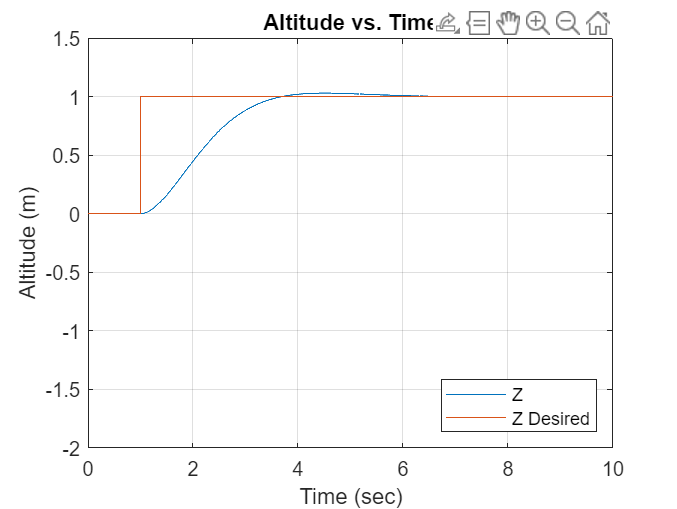

% plot data
figure;
plot(t, z)
hold on
plot(t, z_des)
hold off
grid
axis([0 10 -2 1.5])
title("Altitude vs. Time")
xlabel("Time (sec)")
ylabel("Altitude (m)")
legend("Z", "Z Desired", "Location", "southeast")

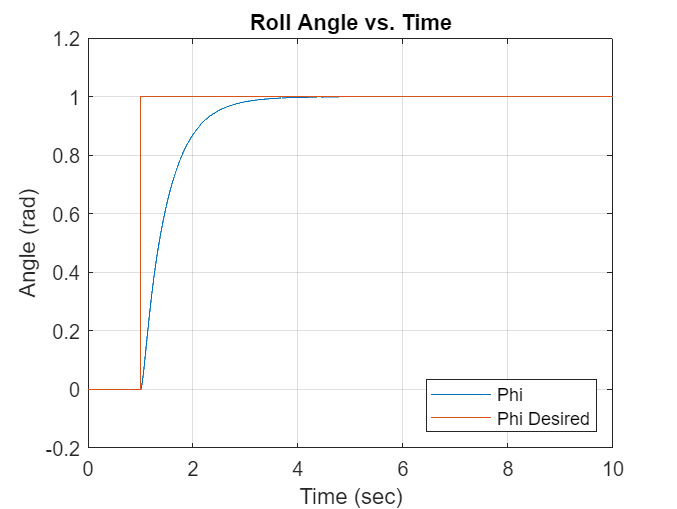


plot(t, phi)
hold on
plot(t, phi_des)
hold off
grid
axis([0 10 -0.2 1.2])
title("Roll Angle vs. Time")
xlabel("Time (sec)")
ylabel("Angle (rad)")
legend("Phi", "Phi Desired", "Location", "southeast")

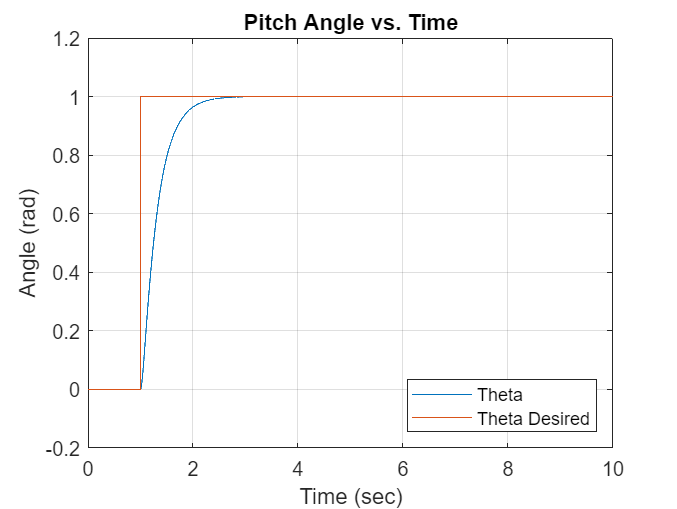


plot(t, theta)
hold on
plot(t, theta_des)
hold off
grid
axis([0 10 -0.2 1.2])
title("Pitch Angle vs. Time")
xlabel("Time (sec)")
ylabel("Angle (rad)")
legend("Theta", "Theta Desired", "Location", "southeast")

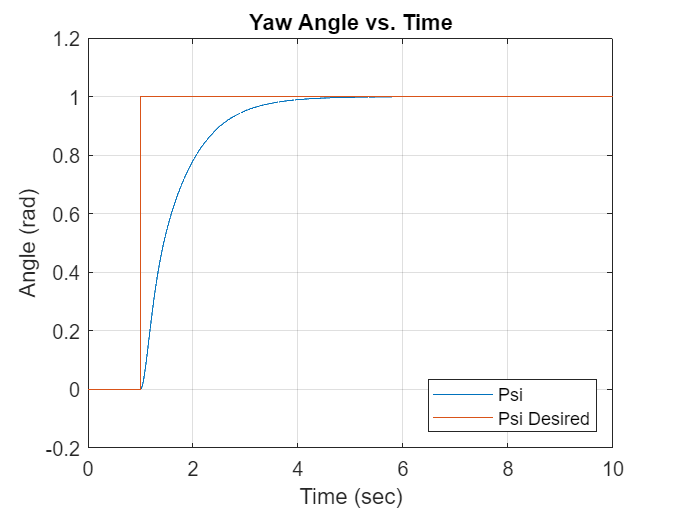


plot(t, psi)
hold on
plot(t, psi_des)
hold off
grid
axis([0 10 -0.2 1.2])
title("Yaw Angle vs. Time")
xlabel("Time (sec)")
ylabel("Angle (rad)")
legend("Psi", "Psi Desired", "Location", "southeast")

i = find(z >= 0.98);
T_s_z = t(i(1)) - 1

T_s_z = 2.5100


i = find(phi >= 0.98);
T_s_phi = t(i(1)) - 1

T_s_phi = 1.9330


i = find(theta >= 0.98);
T_s_theta = t(i(1)) - 1

T_s_theta = 1.1660


i = find(psi >= 0.98);
T_s_psi = t(i(1)) - 1

T_s_psi = 2.5760

z_os = (max(z) - 1) * 100

z_os = 2.9683

phi_os = (max(phi) - 1) * 100

phi_os = -1.3728e-05

theta_os = (max(theta) - 1) * 100

theta_os = 0.0248

psi_os = (max(psi) - 1) * 100

psi_os = -9.6514e-05